# Perform CO2 injection (blackoil module)

MRST Reference: Lie, K.-A., 2019. An Introduction to Reservoir Simulation using MATLAB: [https://doi.org/10.1017/9781108591416](https://doi.org/10.1017/9781108591416) (free PDF)

See also:  [https://www.sintef.no/projectweb/mrst/](https://www.sintef.no/projectweb/mrst/)

Download MRST:  [https://www.sintef.no/projectweb/mrst/download/](https://www.sintef.no/projectweb/mrst/download/)

Example prepared by Lluis Salo-Salgado ([lsalo@mit.edu](mailto:lsalo@mit.edu))

How to run this script: 

1. Download MRST (see link above) 

2. Open MATLAB 

3. Run the startup.m file within the MRST folder 

4. You can now run the script. Note that, the first time you run the model, you'll have to accept the prompts to download and setup AMGCL and boost. MRST takes care of this automatically so you just need to click "OK". This is required to run the fine mesh and large models in general, otherwise Matlab is too slow.

What does this code do? Run a CO2 injection simulation using a mesh with a geometry similar to that in the FluidFlower. We initialize the model with 3 different rock/saturation regions (reservoir, caprock/seal and fault) and full water saturation. We then inject CO2 for a while and let the model run. We consider capillary pressure and dissolution of CO2 in the water. This is a blackoil-type model, so the "gas" phase is the CO2-rich phase, and the "oil" phase is given the properties of water/brine.

% Cleanup and load modules. You will not need ls-proj.
clear, close all
mrstModule add upr ad-props ad-blackoil deckformat ad-core mrst-gui ...
           linearsolvers  
mrstVerbose on

## Output directory and options

% Paths. You'll have to update these!
outputDir = 'C:\Users\huaba0661\OneDrive - University of Bergen\Desktop\Matlab\FluidFlower\mrstExample\Tests';
mesh_path = fullfile(mrstPath('ls-proj'), 'C:\Users\huaba0661\OneDrive - University of Bergen\Desktop\mrst-2024b\FluidFlower\mrstExample\mesh\');
fluid_path = fullfile(mrstPath('ls-proj'), 'C:\Users\huaba0661\OneDrive - University of Bergen\Desktop\mrst-2024b\FluidFlower\mrstExample\fluid_props\');

% Options
mesh    = 'coarse';                             % 'coarse' or 'fine'
wellno  = 1;                                    % 1 or 2 injectors (TBD for 2)
depth    = '1km';                               % '1km' or 'surface' (fluidflower)
if strcmp(depth, 'surface')
    rate     = 8;                               % max inj rate (mL/min) 
    fault_pc = 'low';                           % 'low' or default
    folderName = ['example_mesh_', mesh, '_rate_', num2str(rate), ...
                  '_faultPc_' fault_pc '_depth_' depth];
    disp('******************************************************')
    warning('This will take a long time to run. Are you sure?')
    disp('Press any key to continue. You can cancel now or later with Ctrl + C')
    disp('******************************************************')
    pause 
elseif strcmp(depth, '1km')
    rate      = 80;
    folderName = ['example_mesh_', mesh, '_rate_', num2str(rate), ...
                  '_depth_' depth];
end

% Plots
fig3D = @() figure('Position', [0, 0, 1300, 650]);
alpha = 0.6;
cmap  = jet*alpha + (1-alpha);
setAxProps = @(ax) set(ax, 'View'              , [65, 20]         , ...
                           'PlotBoxAspectRatio', [4.40, 1.86, 1.00], ...
                           'Projection'        , 'Perspective'     , ...
                           'Box'               , 'on'              , ...
                           'ColorMap'          , cmap              );

## 1. Mesh

Load simpleExtrudedMesh

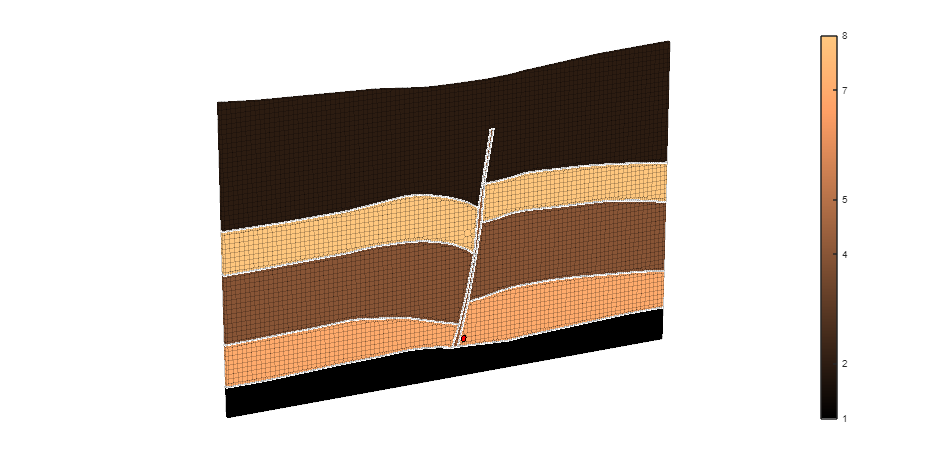

if strcmp(mesh, 'coarse') && strcmp(depth, 'surface')
    G_dat  = load(fullfile(mesh_path, 'simpleExtrudedG_cellSize3cm.mat'));
elseif strcmp(mesh, 'fine') && strcmp(depth, 'surface')
    G_dat  = load(fullfile(mesh_path, 'simpleExtrudedG_cellSize1cm.mat'));
elseif strcmp(mesh, 'coarse') && strcmp(depth, '1km')
    G_dat  = load(fullfile(mesh_path, 'simpleExtrudedG_cellSize3cm_depth1km.mat'));
elseif strcmp(mesh, 'fine') && strcmp(depth, '1km')
    G_dat  = load(fullfile(mesh_path, 'simpleExtrudedG_cellSize1cm_depth1km.mat'));
end
sealID = [1 3 5 8];
faultID = 6;
unitGroups = {5, [4 7], [1 8], [2 9], 3, 6};    % bot to top, fault at the end
G = G_dat.G;

% Plot
fig3D();
%plotCellData(G, G_dat.p)
Ncompart = max(G_dat.p);
cmap = copper(Ncompart);
colr = [1, 7, 4, 8, 2, 5];
for n=1:numel(unitGroups)
    plotCellData(G, colr(n)*ones(sum(ismember(G_dat.p, unitGroups{n})), 1), ...
                 ismember(G_dat.p, unitGroups{n}), 'edgealpha', 0.2)
end
plotGrid(G, find(G_dat.wellNo==1), 'facecolor', 'r')
outlineCoarseGrid(G, G_dat.compartID,'EdgeColor','w','LineWidth',2);
setAxProps(gca), %camlight();
colormap(copper); c = colorbar; set(c, 'YTick', sort(colr));
axis equal off

%ylim([0 1]), zlim([0 1])

## 2. Rock

Here we define the porosity and permeability [L^2] of each grid cell. Layers follow unitGroups (bot to top, left to right for faulted, fault at the end)

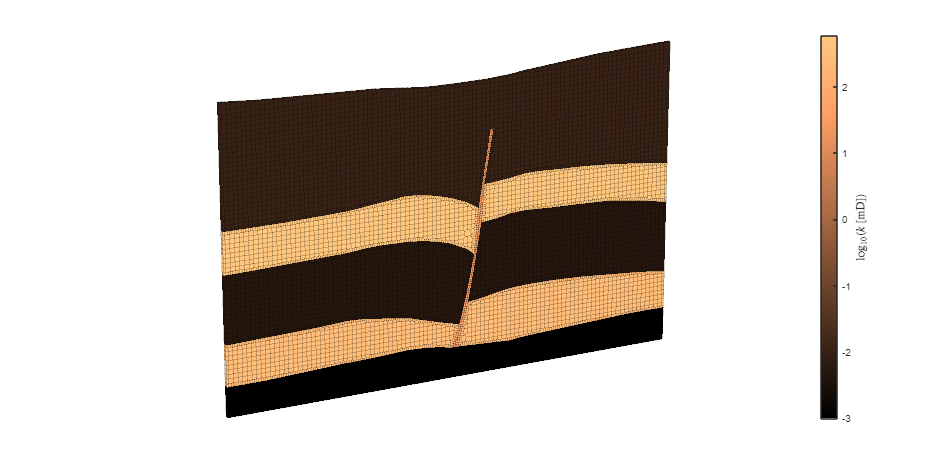

rock.poro = nan(G.cells.num, 1);
rock.perm = nan(G.cells.num, 1);    % isotropic
if strcmp(depth, '1km')
    poroMean = [0.1, 0.3, 0.2, 0.35, 0.27, 0.2];
    permMean = [1e-3, 300, 5e-3, 600, 1e-2, 50];   % [mD]
else
    poroMean = [0.25, 0.4, 0.3, 0.45, 0.27, 0.35];
    permMean = [100, 6000, 1000, 10000, 500, 3000];   % [mD]
end
variation = [];
%rng(S);
for n=1:numel(unitGroups)
    % Cell ids of corresponding unit
    cid = ismember(G_dat.compartID, unitGroups{n});
    nc = sum(cid);

    % Porosity and Permeability
    if strcmp(variation, 'randm')   % random
        S = rng;
        warning(['If simulation cancelled and restarted, you have to' ...
                 'uncomment rng(S) above'])
        r = 0.02;                   % half range for poro
        logr = 0.2;                 % half range for perm
    else
        r = 0;
        logr = 0;
    end
    rock.poro(cid) = (poroMean(n) - r) + rand(nc, 1)*(2*r);
    rock.perm(cid) = 10.^(rand(nc, 1)*(2*logr) + (log10(permMean(n)) - logr));                                            
end
rock.perm = rock.perm*(milli*darcy); % MRST requires SI units

% Plot permeability
fig3D(); plotCellData(G, log10(rock.perm/(milli*darcy)), 'edgealpha', 0.2)
setAxProps(gca), colormap(copper), 
c = colorbar; c.Label.Interpreter = 'latex'; c.Label.FontSize = 11;
c.Label.String = '$\log_{10}(k $ [mD])';
axis equal off

## 3. Fluids

Here we define the fluid properties. This is a blackoil model, so we need a fluid object with the corresponding formation volume factors (FVF) and solution gas oil ratio (Rs). In addition, we need the relative permeability, capillary pressure, surface density of the fluids and rock compressibility The fluid object containing these properties (variable fluid) will have 3 cells for those properties changing from one model region to another (reservoir, caprock and falut).

% Define 3 Saturation regions
rock.regions.saturation = ones(G.cells.num, 1);        % reservoir units
rock.regions.saturation(ismember(G_dat.compartID, sealID)) = 2;
rock.regions.saturation(ismember(G_dat.compartID, faultID)) = 3;

% Define 1 Region for compressibility
rock.regions.rocknum = ones(G.cells.num,1); 

% Load fluid deck from .DATA (ECLIPSE-type) input file and initialize fluid
% The PVT properties of the fluids are obtained by running a thermodynamic 
% model based on Duan & Sun, Chemical Geology (2003) and Spycher et al., 
% Geochimica et cosmochimica acta (2003) fomulations. The implementation
% is described in Hassanzadeh et al., IJGGC (2008).
if strcmp(depth, 'surface')
    if strcmp(fault_pc, 'low')
        fn  = fullfile(fluid_path, 'example_co2brine_shallow_3regions_lowPce.DATA');
    else
        fn  = fullfile(fluid_path, 'example_co2brine_shallow_3regions.DATA');
    end
elseif strcmp(depth, '1km')
    fn  = fullfile(fluid_path, 'example_co2brine_1kmDepth_3regions.DATA');
end
deck = convertDeckUnits(readEclipseDeck(fn));

No converter needed in section 'REGIONS'.
No converter needed in section 'SUMMARY'.
No converter needed in section 'PCUNIT'.


deck.REGIONS.ROCKNUM = rock.regions.rocknum;
fluid = initDeckADIFluid(deck);                 % this is the fluid object


% Plot fluid density and viscosity
% TBD

## 4. Initialize (pressure, saturation, rs, rv)

We compute the hydrostatic distribution numerically, relative to fixed datum point p(z0) = p_r. See MRST book, page 206. Saturation is initialized assuming the full model is water-saturated rs

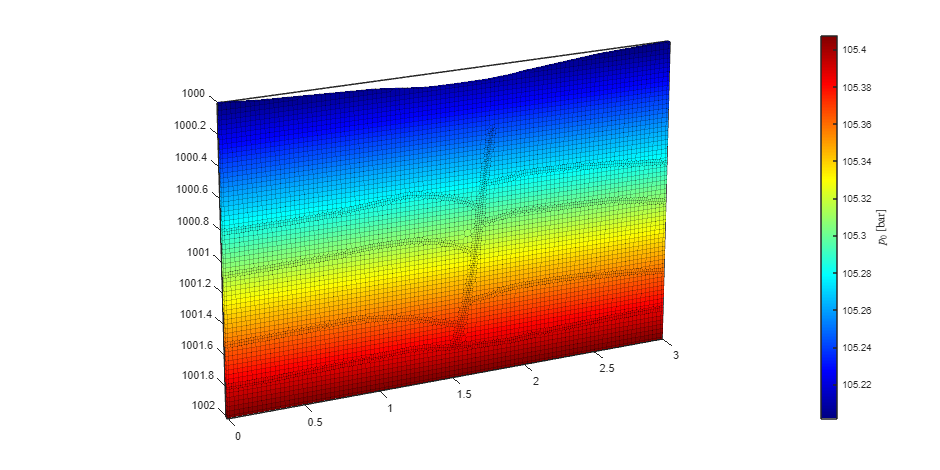

gravity reset on
g = norm(gravity);
rho_wr = fluid.rhoOS*kilogram/meter^3;
if strcmp(depth, 'surface')
    water_column = 0.3;                    % 30 cm of water table on top
elseif strcmp(depth, '1km')
    water_column = 1000;                   % 1km depth
end
p_r = 1*barsa + g*rho_wr*water_column; % p at shallowest z
[z_0, z_max] = deal(min(G.cells.centroids(:,3)), max(G.cells.centroids(:,3)));
equil  = ode23(@(z,p) g .* fluid.bO(p,0,false)*fluid.rhoOS, [z_0, z_max], p_r);
p0 = reshape(deval(equil, G.cells.centroids(:,3)), [], 1);  clear equil
s0  = repmat([1, 0], [G.cells.num, 1]);  % s: fully saturated in oil --> 
                                         %    [0 1 0] if 'WOG'; [1 0] if 'OG'
rs0 = zeros(G.cells.num, 1);             % no dissolved gas at the beginning
rv0 = 0;                                 % dry gas
state0 = struct('s', s0, 'rs', rs0, 'rv', rv0, 'pressure', p0);

% plot
fig3D(); plotCellData(G, p0/barsa, 'edgealpha', 0.2)
setAxProps(gca), colormap(jet), c = colorbar;
c.Label.Interpreter = 'latex'; c.Label.FontSize = 11;
c.Label.String = '$p_0 $ [bar]';
axis equal %off

## 5. Wells

All times are defined in sec in MRST, so we convert them to sec.

if strcmp(depth, 'surface')
    t = [5*minute 5*hour 2*day];                     % rampup, injtime, simtime                          
    reportTimes = [(1:t(1)/minute)*minute, ...       % rampup inj rate
                   (10:10:300)*minute, ...           % injection
                   (301:300+t(1)/minute)*minute, ... % rampdown inj rate
                   [310 315 320:10:2880]*minute];    % rest
elseif strcmp(depth, '1km')
    t = [60*minute 1*day 3*year];
    reportTimes = [(12:12:t(1)/minute)*minute, ...
                   (2:1:24)*hour, ...
                   (1440+5:5:1465)*minute, ... 
                   ([26:2:48 54:6:96 108 120])*hour, ...
                   [6:30 40:10:90 105 120:30:330 365]*day, ... 
                   (1.2:.2:3)*year];
end
injrate = rate*(milli*litre)/(minute*wellno);    % volumetric rate in [Sm^3/s]
%injvol = injrate*t(2);
%rhoInj = fluid.rhoGS;
%mrate = injvol*rhoInj/(t(2)*wellno);            
wellInx = find(G_dat.wellNo==1);                 % Well cell id
W = addWell([ ], G, rock, wellInx, 'Name', 'I1', 'Dir', 'z', ...
            'Type', 'rate', 'Val', injrate, 'compi', [0, 1], ...    % order 'OG'
            'refDepth', G.cells.centroids(wellInx, G.griddim), ...
            'Radius', 0.9*1e-3);                                
timesteps = [reportTimes(1) diff(reportTimes)];
assert(sum(timesteps)==t(end), 'sum of timesteps must equal simTime')

## 6. Model

Here we put together the blackoil model, and define the acceleration and solver parameters.

model = GenericBlackOilModel(G, rock, fluid, 'disgas', true, 'water', false);

% Acceleration and solver parameters
model.AutoDiffBackend = DiagonalAutoDiffBackend('useMex', true, ...
                                                'deferredAssembly', true);
if strcmp(depth, 'surface')
    model.toleranceCNV = 3e-3;      % relax a bit
end
model.dsMaxAbs = 0.05;
model.minimumPressure = min(state0.pressure);
model = model.validateModel();                                            

Setting up FlowPropertyFunctions... Ok.
Setting up PVTPropertyFunctions... Ok.
Setting up FlowDiscretization... Ok.


nls = getNonLinearSolver(model, 'TimestepStrategy', 'iteration', ...
                         'useCPR', true);
nls.useLinesearch = true;
nls.useRelaxation = false;
nls.maxIterations = 12;      
nls.maxTimestepCuts = 16; 
if strcmp(mesh, 'fine')
    nls.acceptanceFactor = 5;
else
    nls.acceptanceFactor = 2;
end

## BCs

We set constant pressure at the top, and no-flow in the other boundaries. These are the actual BCs for the physical fluidflower. By default, MRST uses no-flow BCs everywhere. So, we just need to apply constant pressure on the top faces. 

For the '1km' depth case, we impose no-flow everywhere, but we recreate an open aquifer system by multiplying the pore volumes of external cells by a very large number.

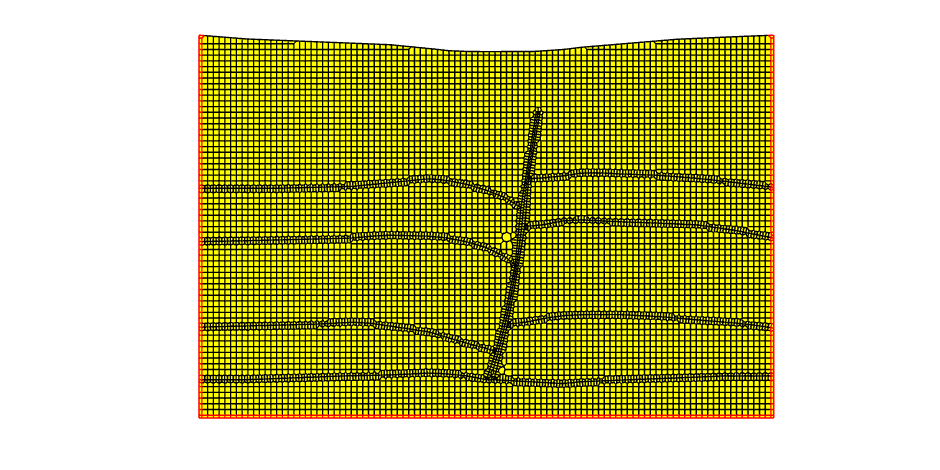

g = norm(gravity);

if strcmp(depth, 'surface')
    % First, we need to find the model top faces where we apply constant p
    f = false(G.faces.num, 1);
    f(boundaryFaces(G)) = true;
    zmean = mean(G.cells.centroids(:, 3));
    f = all([G.faces.centroids(:, 3) < zmean, f], 2);
    f = all([f, abs(G.faces.normals(:, 3)) > abs(0.9*G.faces.normals(:, 2))], 2);
    f = find(all([f, abs(G.faces.normals(:, 3)) > abs(0.9*G.faces.normals(:, 1))], 2));
    f(G.faces.centroids(f,3)>0.1) = [];

    % plot
    fig3D(); plotFaces(G); plotFaces(G, f, 'edgecolor', 'r', 'facecolor', 'none')
    setAxProps(gca), colormap(jet), axis equal off

    % Now that we have the faces, we compute the actual pressure values
    % (similar to what we did to initialize the cell pressures) and assign
    % that pressure to the faces.
    [z_0, z_max] = deal(min(G.faces.centroids(f,3)), max(G.faces.centroids(f,3)));
    equil  = ode23(@(z,p) g .* fluid.bO(p,0,false)*fluid.rhoOS(1), [z_0, z_max], p_r);
    fp_val = reshape(deval(equil, G.faces.centroids(f,3)), [], 1);  clear equil
    bc = addBC([], f, 'pressure', fp_val, 'sat', [1, 0]);

elseif strcmp(depth, '1km')
    % Find external faces
    L = max(G.faces.centroids(:,2));
    D = max(G.faces.centroids(:,3));
    f = any([G.faces.centroids(:,2) == 0, ...
             G.faces.centroids(:,2) > L-1e-3, ...
             G.faces.centroids(:,3) > D-1e-3], 2);
    %fig3D(); plotFaces(G); plotFaces(G, f, 'edgecolor', 'r', 'facecolor', 'none')
    %setAxProps(gca), colormap(jet), axis equal off

    % Find external cells
    cellsext = unique(reshape(G.faces.neighbors(f, :), [], 1));
    cellsext(cellsext==0) = [];
    model.operators.pv(cellsext) = model.operators.pv(cellsext)*10^9;
    bc = [];

    % plot
    fig3D(); plotGrid(G); hold on, plotGrid(G, cellsext, 'edgecolor', 'r')
    setAxProps(gca), axis equal off, view([90 0]) 
end

## Schedule

Here we set up the injection schedule, with proper controls so that we can have changing injection rates.

schedule_inj = simpleSchedule(timesteps, 'W', W, 'bc', bc);      
n_ramp = 5;
v = injrate;
injrates = [0.01*v 0.1*v 0.2*v 0.5*v v ...      % we ramp up in n_ramp steps
            0.8*v 0.5*v 0.1*v 0.01*v 0];
tmp = cell(numel(injrates), 1);                 % create 2 schedules
schedule = struct('step', schedule_inj.step);   % timesteps and wells for each timestep
schedule.control = struct('W', tmp, 'bc', tmp, 'src', tmp); 

% Update injection rates
for n=1:numel(injrates)
    schedule.control(n).W = W;                   % make a copy of well params
    schedule.control(n).W.val = injrates(n);     % update injrate
    schedule.control(n).bc = bc;                 % same BCs
end

% Finally, indicate the index of the well to be used in each timestep
idStep = find(cumsum(schedule.step.val) < t(1));
schedule.step.control(idStep) = 1:max(idStep);
schedule.step.control(idStep(end)+1:end) = max(idStep)+1;
idStep2 = find(cumsum(schedule.step.val) > t(2), 1);
schedule.step.control(idStep2:idStep2+(n_ramp -1)) = (1:n_ramp) + n_ramp;
schedule.step.control(idStep2+n_ramp:end) = 2*n_ramp;

## Simulation

For each timestep, MRST will save three files in the folder indicated in outputDir: 

- report: contains info on the number of iterations and convergence, etc 

- states: solution structure with p, saturation, etc 

- wellSols: well parameters such as bhp and such 

For this model (fine mesh) the full simulation will take less than 1GB of space (all archives within outputDir). The simulation time is variable depending on hardware, but if you are using MEX and AMGCL it should be finished in minutes for the 'coarse' mesh and '1km' case. The 'fine' mesh and 'surface' cases will take hours to a few days, and a dedicated PC/workstation is suggested so that you don't have a simulation running in the background for so long. MRST will save each timestep in the outputDir, so if the simulation is stopped at any point, you can restart it later from where you left off.

 N = 4;                                       % depending on your hardware           
 maxNumCompThreads(N);   
 % nls.LinearSolver.amgcl_setup.nthreads = N;   % Specify threads manually
if isfield(nls.LinearSolver, 'amgcl_setup.nthreads')
    nls.LinearSolver.amgcl_setup.nthreads = N;   % Specify threads manually
end
problem = packSimulationProblem(state0, model, schedule, folderName, ...
                                'Name', folderName, 'Directory', outputDir, ...
                                'NonLinearSolver', nls);
[ok, status] = simulatePackedProblem(problem);

*****************************************************************************************
* Case "example_mesh_coarse_rate_80_depth_1km" (example_mesh_coarse_rate_80_depth_1km)  *
* Description: "example_mesh_coarse_rate_80_depth_1km_GenericBlackOilModel"             *
*****************************************************************************************
-> Complete output found, nothing to do here.


[wellSols, states, report] = getPackedSimulatorOutput(problem);

Found complete data for example_mesh_coarse_rate_80_depth_1km (example_mesh_coarse_rate_80_depth_1km): 106 steps present


## Results

Compute quantitites

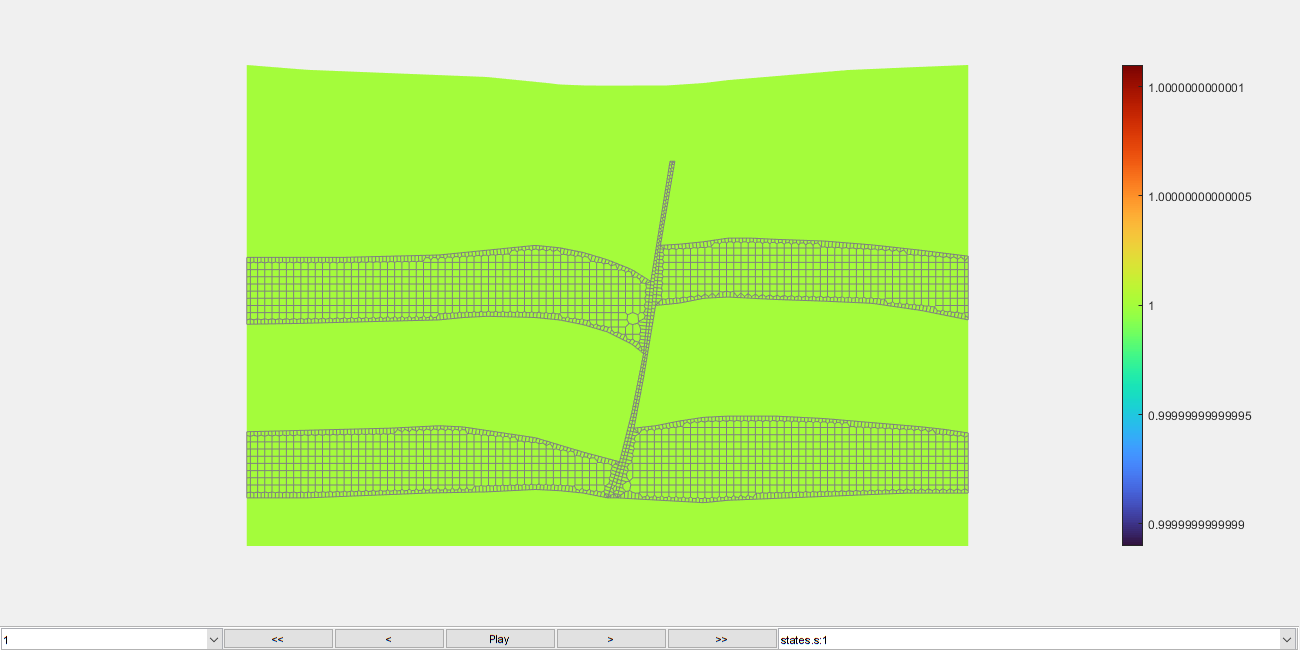

model = model.validateModel();
for n=1:numel(states)
    states{n}.dp = states{n}.pressure - state0.pressure;  
    %pc = model.getProp(states{n}, 'CapillaryPressure');
    %states{n}.FlowProps.CapillaryPressure = pc{1,2};
    %states{n}.FlowProps.RelativePermeability = model.getProp(states{n}, ...
    %                                                 'RelativePermeability');
end
states{1}.reg = model.rock.regions.saturation;

% Basic overview
noSeal = find(ismember(G_dat.compartID, ...
                        [unitGroups{2} unitGroups{4} unitGroups{end}]));
fig3D(); plotToolbar(G, states, 'edgealpha', 0.2); 
plotGrid(G, noSeal, 'edgecolor', [0.5 0.5 0.5], 'facecolor', 'none');
setAxProps(gca), colormap(turbo), c = colorbar; %clim([0 40000])
axis equal off
view([90 0])

%set(gca, 'ColorScale', 'log')
%caxis([1e-8 1])

% See also plotCellData.m